% Set the folder path for the data
folder_path = 'X:\Qiang\0-mWAKE-Cre-Gcamp-EEG-NEW';

% User input for decision to plot or not
plotting = input('Do you want to plot? (yes/no)\n', 's');

if strcmp(plotting,'y') || strmcp(plotting,'yes')
    plotting = 1;
else
    plotting=0;
end

% Create an instance of the 'io' class to handle file input/output operations
my_io = io(folder_path);

% Create a table containing information about the data files
result_table = my_io.create_table();

% Create an instance of the 'DataProcessor' class to process the data
data_processor = DataProcessor(result_table);

% Initialize a table to store the combined data
combined_data = table();
combined_transients = table();
combined_transitions = table();

% Loop through each row of the result_table
for row_idx = 1:height(result_table)
    % Get the current row from the data_table and the fiber_dir
    row = data_processor.data_table(row_idx, :);
    data_processor.current_row = row_idx;
    fiber_dir = row.fiber_dir{1};

    % Define processed data file paths
    parent_folder = fileparts(fiber_dir);
    fiber_chunks_file = fullfile(parent_folder,'processed_data','fiber_chunks_with_scores.mat');
    eeg_chunks_file = fullfile(parent_folder,'processed_data','eeg_chunks_table.mat');

    % Check if the processed files exist
    if ~exist(fiber_chunks_file, 'file') || ~exist(eeg_chunks_file, 'file')
        % Load data for the current row
        data_processor = data_processor.load_row(row_idx);

        % Combine EEG and score data
        data_processor = data_processor.create_comb_eeg_score();

        % Decimate fiber data with a decimation factor of 31
        data_processor = data_processor.decimate_fiber_data(31);

        % Process the fiber data
        fiber_chunks = data_processor.proc_fiber();

        % Get the corresponding EEG data chunks for the fiber_chunks
        eeg_chunks_table = data_processor.get_eeg_chunks(fiber_chunks);

        % Add scores to the fiber_chunks
        fiber_chunks_with_scores = data_processor.add_scores_to_fiber_chunks(fiber_chunks);

        % Save the processed data
        io.save_processed_data(fiber_dir, fiber_chunks_with_scores, eeg_chunks_table);
    else
        % Load the processed files
        disp('Loading processed chunks...' )
        load(fiber_chunks_file, 'fiber_chunks_with_scores');
        load(eeg_chunks_file, 'eeg_chunks_table');
    end


    data_processor = data_processor.process_cell_array(fiber_chunks_with_scores)
    data_processor = data_processor.calc_score_summary();



    % Calculate the ZT and mouse values for the current row
    ZT = io.extract_zt(row);
    mouse = str2double(regexp(row.mouse_dir{1}, '(?<=animal\s)\d+', 'match'));

    % Add ZT and mouse columns to the score_avgs table
    data_processor.score_avgs.ZT = repmat({ZT}, height(data_processor.score_avgs), 1);
    data_processor.score_avgs.mouse = repmat(mouse, height(data_processor.score_avgs), 1);

    % Calculate transients
    [transient_results , locs]= data_processor.calculatePeaks();
    transient_results.ZT = repmat({ZT}, height(transient_results), 1);
    transient_results.mouse = repmat(mouse, height(transient_results), 1);

    % Calculate transitions
    transition_results = data_processor.extractTransitions(10);
    transition_results.ZT = repmat({ZT}, height(transition_results), 1);
    transition_results.mouse = repmat(mouse, height(transition_results), 1);

    % Concatenate transients
    combined_transients = [combined_transients; transient_results];

    % Concatenate transients
    combined_transitions = [combined_transitions; transition_results];


    % Concatenate the score_avgs table with the combined_data table
    combined_data = [combined_data; data_processor.score_avgs];

    if plotting
        % Create an instance of the 'Plotter' class
        my_plotter = Plotter();

        % Plot the fiber_chunks_with_scores for the current row
        my_plotter.plot_fiber_chunks_with_scores(row, fiber_chunks_with_scores, fiber_dir);
        my_plotter.plot_summary(data_processor,parent_folder)
        %my_plotter.plotDataChunks(fiber_chunks_with_scores,eeg_chunks_table,data_processor.fiber_fs,400,parent_folder,10)

    end


end

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: []
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 1
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 2
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 3
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 4
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 5
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 6
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 7
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 8
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 9
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 10
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 11
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 12
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 13
           score_data: []
             eeg_data: []
           fiber_data: []


Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
      cutOffFrequency: 5
            peak_data: []
           data_table: [14×5 table]
          current_row: 14
           score_data: []
             eeg_data: []
           fiber_data: []


% Define the path and filename for the output .csv file
output_file = fullfile(folder_path,'combined_data.csv');

% Save the combined_data table as a .csv file
writetable(combined_data, output_file);

% Save the combined_transients table as .csv file
DataProcessor.saveCombinedTransientStatistics(combined_transients,folder_path)


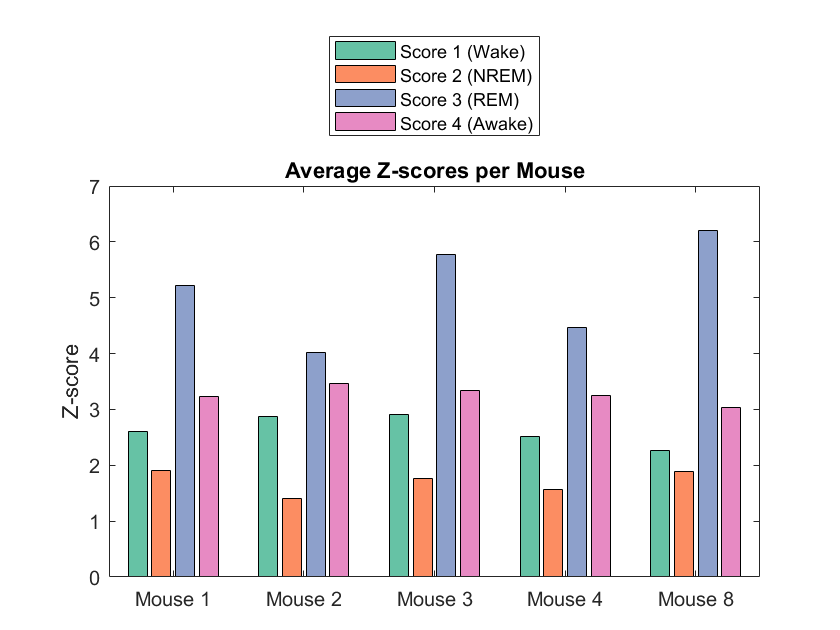

% Plotting
% Plot average z scores per mouse
my_plotter = Plotter();
my_plotter.plot_avg_z_scores_per_mouse(combined_data,folder_path);

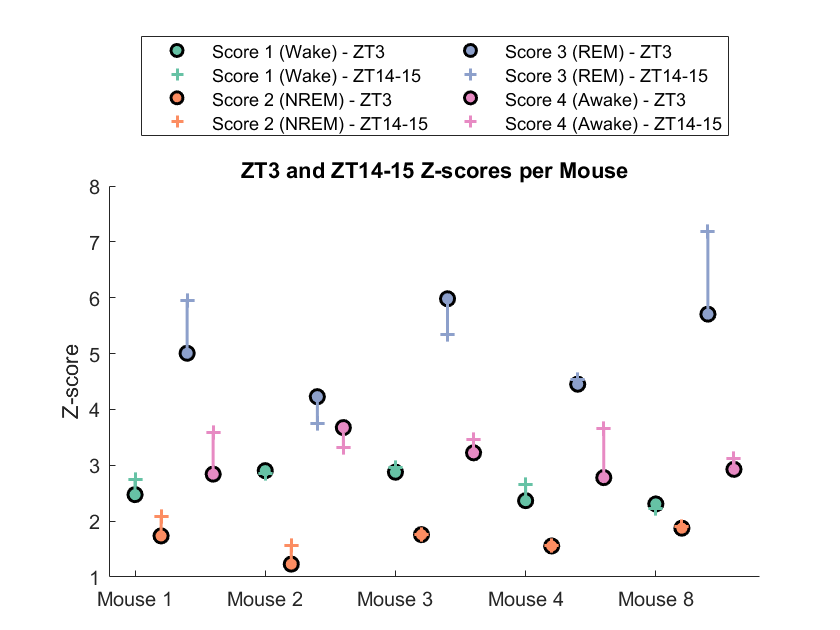


% Plot average z scores by trial
my_plotter.plotZTScores(combined_data,folder_path);

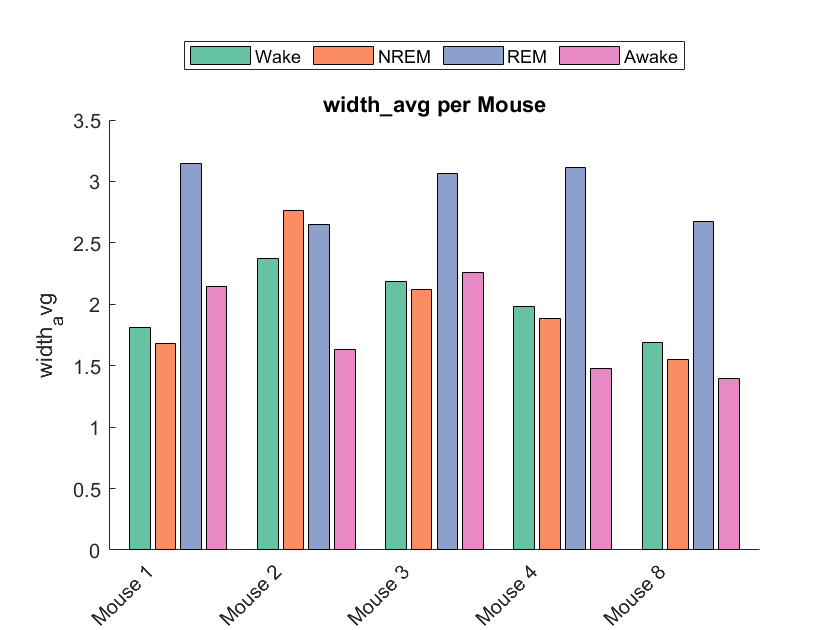

% Plot summary statistics, treats all data same, no seperation of ZT3 or
% ZT15
Plotter.plotSummaryStatistics(combined_transients,folder_path)

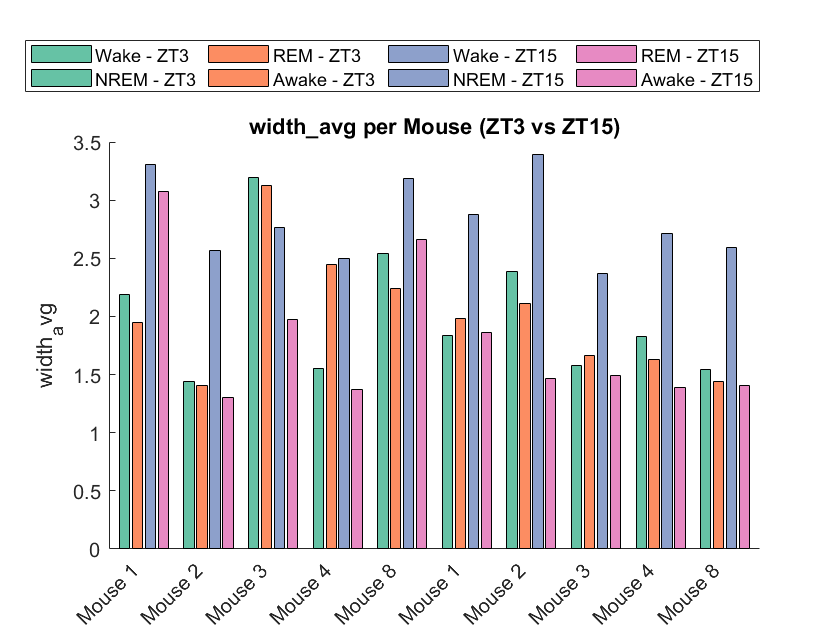

% Plot Transition heatmaps
Plotter.plotTransitionHeatmaps(combined_transitions,1,1,data_processor.fiber_fs)

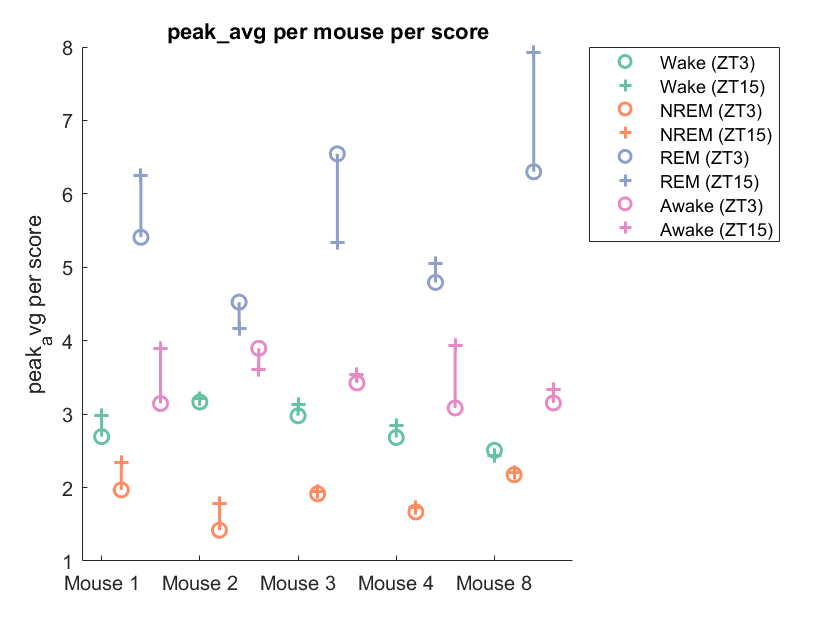

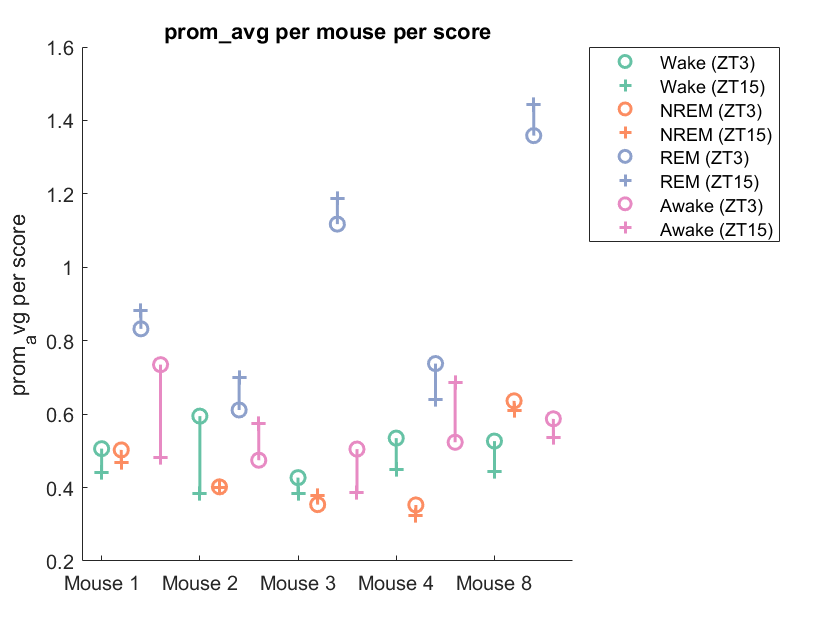

% Plot Scatter plots with ZT3 and ZT15 compared
Plotter.plotSummaryStatisticsScatterComparison(combined_transients,folder_path)